## **AERO95002 Numerical Analysis 2019-2020**

## **Coursework 1**

## **Dr. Elnaz Naghibi**

## **Due Date: 17 February 2020**

### **Question 1 [15%]**

Plot the function $f\left(x\right)=\cos \;x\;\left(e^{2x} -2e^x +1\right)$ in the interval $\left\lbrack -\pi /4,3\pi /4\right\rbrack$ and find its roots using MATLAB functions.

Explore the four methods of root finding discussed in the lecture notes and select an efficient method to find each root. Discuss your rationale and provide the code presenting the most efficient method for each root. Show the convergence to each root using appropriate plots. Finally, compare the number of iterations required to obtain each root and discuss the reason behind the difference in convergence rates of the two roots.

**Answer:**

You can use this space to explain the answers and include equations as needed using either Latex code or the live script equation editor from the tab "insert".

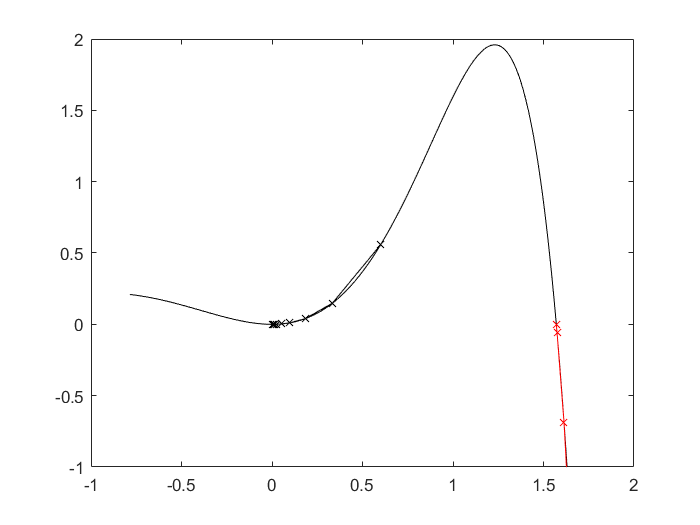

% Use this box for coding. 
% Outputs and graphs will be displayed on the right panel.
% To avoid submitting multiple files, please include functions at the bottom of your scripts.
%%coded by Jiaxuan Tang; CID:01486551;
%Question1;


clear
clc

x = -pi/4:0.01:pi*3/4;
%plot the diagram
%use newton method
plot(x,fx(x),'-k');
hold on;

ylim([-1 2]);
tolerance = 0.000000001;

x0 = 3;
count1=0;
converg1=[];
xData1=[];
while abs(fx(x0)) > tolerance
    converg1 = [converg1,fx(x0)];
    xData1=[xData1,x0];
    x1 = x0 - fx(x0)/fbarX(x0);
    x0 = x1;
    count1 = count1 +1;
    hold on
end
plot(xData1,converg1,'-xr');

x0_2 =0.6;
count2 = 0;
converg2=[];
xData2=[];
while abs(fx(x0_2)) > tolerance
    converg2 = [converg2,fx(x0_2)];
    xData2=[xData2,x0_2];
    x1_2 = x0_2 - fx(x0_2)/fbarX(x0_2);
    x0_2 = x1_2;
    count2 = count2 + 2;
    hold on
end
plot(xData2,converg2,'-xk');
hold off;


disp(count1);

     9



disp(count2);

    30



fprintf('The root of this function is %4.3f and %4.3f.',x0,x0_2);

The root of this function is 1.571 and 0.000.

### **Question 2 [30%]**

**Part a:  [15 %]**

Calculate Legendre polynomial of degree 5 using equation 16 in Handout_4 and MATLAB symbolic toolbox. Compare your resulting polynomial with "legendreP" function in MATLAB. Plot this function in the interval $\left\lbrack -1\ldotp 1\right\rbrack$ and calculate its roots $\eta_i$. Calculate weighting coefficients $w_i$ using the definition in equation 21. Using  $\eta_i$ and $w_i$, calculate the integral of $\int_{-1}^2 \left({\textrm{ax}}^9 +{\textrm{bx}}^4 +\textrm{cx}\right)\;\textrm{dx}$ and show that it will be the same as its analytical value.

**Answer:**

%%Question 2a

clear
clc

N=5;
syms x;
Ln=1./(2.^N.*factorial(N)).*diff((x.^2-1).^N,N);
disp(simplify(Ln));

$$\frac{x\,\left(63\,x^{4}-70\,x^{2}+15\right)}{8}$$

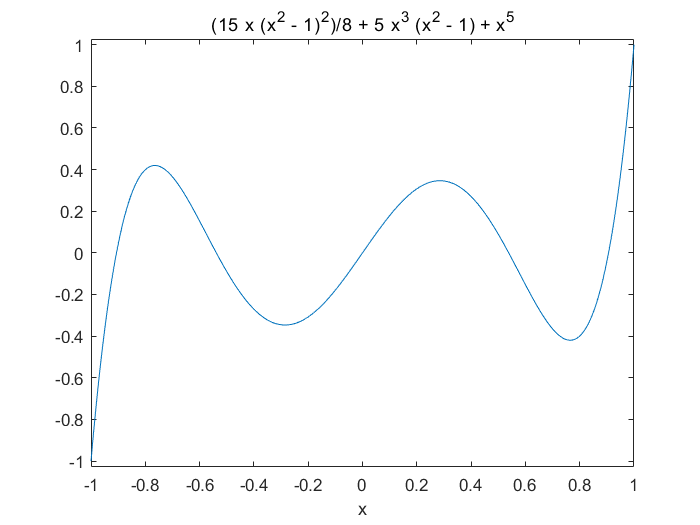

%plot the graph of Ln over x
ezplot(Ln,[-1,1]);

LnM = legendreP(5,x);
disp(LnM);

$$\frac{63\,x^{5}}{8}-\frac{35\,x^{3}}{4}+\frac{15\,x}{8}$$

%solve the integral of the equation
%using t to substitute x,(2x-1)/3

%get roots
ni=solve(Ln,x);
%ni calculated(roots of the ln equation)
disp(ni);

$$\left(\begin{array}{c} 0\\ -\sqrt{\frac{5}{9}-\frac{2\,\sqrt{2}\,\sqrt{35}}{63}}\\ -\sqrt{\frac{2\,\sqrt{2}\,\sqrt{35}}{63}+\frac{5}{9}}\\ \sqrt{\frac{5}{9}-\frac{2\,\sqrt{2}\,\sqrt{35}}{63}}\\ \sqrt{\frac{2\,\sqrt{2}\,\sqrt{35}}{63}+\frac{5}{9}} \end{array}\right)$$

wi = 2./(1-(ni).^2)*(diff(Ln,1)).^(-2);%calculate the weigh coefficient
valWi=[];

for i=1:5
    valWi(i) = subs(wi(i),x,ni(i));%substituteni to get weight coefficients
end
fprintf('The weight coefficient is %3.3f ;\n',valWi);

The weight coefficient is 0.569 ;
The weight coefficient is 0.479 ;
The weight coefficient is 0.237 ;
The weight coefficient is 0.479 ;
The weight coefficient is 0.237 ;


fprintf('The root is %3.4f respectively ;\n',ni);

The root is 0.0000 respectively ;
The root is -0.5385 respectively ;
The root is -0.9062 respectively ;
The root is 0.5385 respectively ;
The root is 0.9062 respectively ;


%calculate the integration
dy = (valWi*fx2B(x2t(ni))).*3/2;

fprintf('The integral of this equation is %3.3f',dy);

The integral of this equation is 321.600

funIntegral = @(x) 3.*x.^9+2.*x.^4+1.*x;
intEqn = integral(funIntegral,-1,2);
fprintf('The integral of this equation using the internal function is %3.3f',intEqn);

The integral of this equation using the internal function is 321.600

**Part b: [15 %]**

Use mid-point, trapezium and Simpson integration schemes to calculate the below integrals for $n=25,50,100,200$ and provide the code for each method accordingly.


$$\int_0^{3\pi } \textrm{sinx}\;\textrm{dx}$$



$$\int_0^{3\pi } \left|\textrm{sinx}\right|\;\textrm{dx}$$



$$\int_0^{3\pi } \sin^2 x\;\textrm{dx}$$


Calculate the errors for every value of $n$ using analytical values of integration and list the order of accuracy of the schemes as you double $n$ in each round. Compare your calculated orders of accuracy with theoretical values in chapter 3.2 of the text book "‘Fundamentals of Engineering Numerical Analysis". Discuss how different choices of integrand functions can affect the order of accuracy in the numerical schemes. 

**Answer:**

%%question 2b
clear
clc

%change n in each iteration
n=[25,50,100,200];

%initialize the integral
IntSinMid = zeros(4,1);
IntAbsSinMid = zeros(4,1);
IntSin2Mid = zeros(4,1);

IntAbsSinTrapz = zeros(4,1);
IntSinTrapz = zeros(4,1);
IntSin2Trapz = zeros(4,1);

IntSinSim = zeros(4,1);
IntAbsSinSim = zeros(4,1);
IntSin2Sim = zeros(4,1);


%mid-point rule;
for num = 1:4
    h1(num) = 3*pi/n(num);

    for i = 0:n(num)-1
        xmi(num) = 0 + h1(num)*((2*i + 1)/2);
    
        IntSinMid(num) = IntSinMid(num) + h1(num)*sin(xmi(num));
        IntAbsSinMid(num) = IntAbsSinMid(num) + h1(num)*abs(sin(xmi(num)));
        IntSin2Mid(num) = IntSin2Mid(num) + h1(num)*sin(xmi(num))^2;
    
    end

    %Trapezium rule
    xi=zeros(4,1);

    for i = 1:n(num)
        xi(num, i+1) = 0 + i*h1(num);
    end

    for i = 1:n(num)
        IntSinTrapz(num) = IntSinTrapz(num) + h1(num)*((sin(xi(num,i)) + sin(xi(num,i+1)))/2);
        IntAbsSinTrapz(num) = IntAbsSinTrapz(num) + h1(num)*((abs(sin(xi(num,i))) + abs(sin(xi(num,i+1))))/2);
        IntSin2Trapz(num) = IntSin2Trapz(num) + h1(num)*((sin(xi(num,i))^2 + sin(xi(num,i+1))^2)/2);
    end

    %simpson rule
    for i = 0:n(num)
        if mod(i,2) == 0
            if (i==0) || (i==n(num))
                IntSinSim(num) = IntSinSim(num) + sin(xi(num,i+1));
                IntAbsSinSim(num) = IntAbsSinSim(num) + abs(sin(xi(num,i+1)));
                IntSin2Sim(num) = IntSin2Sim(num) + sin(xi(num,i+1))^2;
            else
                IntSinSim(num) = IntSinSim(num) + 2*sin(xi(num,i+1));
                IntAbsSinSim(num) = IntAbsSinSim(num) + 2*abs(sin(xi(num,i+1)));
                IntSin2Sim(num) = IntSin2Sim(num) + 2*sin(xi(num,i+1))^2;
            end
    
        else
            IntSinSim(num) = IntSinSim(num) + 4*sin(xi(num,i+1));
            IntAbsSinSim(num) = IntAbsSinSim(num) + 4*abs(sin(xi(num,i+1)));
            IntSin2Sim(num) = IntSin2Sim(num) + 4*sin(xi(num,i+1))^2;
        end
    end
    IntSinSim(num) = h1(num)/3*IntSinSim(num);
    IntAbsSinSim(num) = h1(num)/3*IntAbsSinSim(num);
    IntSin2Sim(num) = h1(num)/3*IntSin2Sim(num);

end

enum = 4;%can be changed
fun1 = @(x) sin(x);
IntAnalyticalSin = integral(fun1,0,3*pi);

fun2 = @(x) abs(sin(x));
IntAnalyticalAbsSin = integral(fun2,0,3*pi);

fun3 = @(x) sin(x).^2;
IntAnalyticalSin2 = integral(fun3,0,3*pi);

%Simpson method for n=25 Doesn't exist;
%calculation of error for each n here
errorFun1Mid25 = IntSinMid(1) - IntAnalyticalSin;
errorFun1Sim25 = IntSinSim(1) - IntAnalyticalSin;
errorFun1Trapz25 = IntSinTrapz(1) - IntAnalyticalSin;

errorFun2Mid25 = IntAbsSinMid(1) - IntAnalyticalAbsSin;
errorFun2Sim25 = IntAbsSinSim(1) - IntAnalyticalAbsSin;
errorFun2Trapz25 = IntAbsSinTrapz(1) - IntAnalyticalAbsSin;

errorFun3Mid25 = IntSin2Mid(1) - IntAnalyticalSin2;
errorFun3Sim25 = IntSin2Sim(1) - IntAnalyticalSin2;
errorFun3Trapz25 = IntSin2Trapz(1) - IntAnalyticalSin2;


errorFun1Mid50 = IntSinMid(2) - IntAnalyticalSin;
errorFun1Sim50 = IntSinSim(2) - IntAnalyticalSin;
errorFun1Trapz50 = IntSinTrapz(2) - IntAnalyticalSin;

errorFun2Mid50 = IntAbsSinMid(2) - IntAnalyticalAbsSin;
errorFun2Sim50 = IntAbsSinSim(2) - IntAnalyticalAbsSin;
errorFun2Trapz50 = IntAbsSinTrapz(2) - IntAnalyticalAbsSin;

errorFun3Mid50 = IntSin2Mid(2) - IntAnalyticalSin2;
errorFun3Sim50 = IntSin2Sim(2) - IntAnalyticalSin2;
errorFun3Trapz50 = IntSin2Trapz(2) - IntAnalyticalSin2;


errorFun1Mid100 = IntSinMid(3) - IntAnalyticalSin;
errorFun1Sim100 = IntSinSim(3) - IntAnalyticalSin;
errorFun1Trapz100 = IntSinTrapz(3) - IntAnalyticalSin;

errorFun2Mid100 = IntAbsSinMid(3) - IntAnalyticalAbsSin;
errorFun2Sim100 = IntAbsSinSim(3) - IntAnalyticalAbsSin;
errorFun2Trapz100 = IntAbsSinTrapz(3) - IntAnalyticalAbsSin;

errorFun3Mid100 = IntSin2Mid(3) - IntAnalyticalSin2;
errorFun3Sim100 = IntSin2Sim(3) - IntAnalyticalSin2;
errorFun3Trapz100 = IntSin2Trapz(3) - IntAnalyticalSin2;


errorFun1Mid200 = IntSinMid(4) - IntAnalyticalSin;
errorFun1Sim200 = IntSinSim(4) - IntAnalyticalSin;
errorFun1Trapz200 = IntSinTrapz(4) - IntAnalyticalSin;

errorFun2Mid200 = IntAbsSinMid(4) - IntAnalyticalAbsSin;
errorFun2Sim200 = IntAbsSinSim(4) - IntAnalyticalAbsSin;
errorFun2Trapz200 = IntAbsSinTrapz(4) - IntAnalyticalAbsSin;

errorFun3Mid200 = IntSin2Mid(4) - IntAnalyticalSin2;
errorFun3Sim200 = IntSin2Sim(4) - IntAnalyticalSin2;
errorFun3Trapz200 = IntSin2Trapz(4) - IntAnalyticalSin2;


%calculation of order of accuracy using array to store
orderOfAccuracy_1Mid(1) = log2(abs(errorFun1Mid25/errorFun1Mid50));
orderOfAccuracy_1Mid(2) = log2(abs(errorFun1Mid50/errorFun1Mid100));
orderOfAccuracy_1Mid(3) = log2(abs(errorFun1Mid100/errorFun1Mid200));

orderOfAccuracy_2Mid(1) = log2(abs(errorFun2Mid25/errorFun2Mid50));
orderOfAccuracy_2Mid(2) = log2(abs(errorFun2Mid50/errorFun2Mid100));
orderOfAccuracy_2Mid(3) = log2(abs(errorFun2Mid100/errorFun2Mid200));

orderOfAccuracy_3Mid(1) = log2(abs(errorFun3Mid25/errorFun3Mid50));
orderOfAccuracy_3Mid(2) = log2(abs(errorFun3Mid50/errorFun3Mid100));
orderOfAccuracy_3Mid(3) = log2(abs(errorFun3Mid100/errorFun3Mid200));


orderOfAccuracy_1Trapz(1) = log2(abs(errorFun1Trapz25/errorFun1Trapz50));
orderOfAccuracy_1Trapz(2) = log2(abs(errorFun1Trapz50/errorFun1Trapz100));
orderOfAccuracy_1Trapz(3) = log2(abs(errorFun1Trapz100/errorFun1Trapz200));

orderOfAccuracy_2Trapz(1) = log2(abs(errorFun2Trapz25/errorFun2Trapz50));
orderOfAccuracy_2Trapz(2) = log2(abs(errorFun2Trapz25/errorFun2Trapz50));
orderOfAccuracy_2Trapz(3) = log2(abs(errorFun2Trapz25/errorFun2Trapz50));

orderOfAccuracy_3Trapz(1) = log2(abs(errorFun3Trapz25/errorFun3Trapz50));
orderOfAccuracy_3Trapz(2) = log2(abs(errorFun3Trapz50/errorFun3Trapz100));
orderOfAccuracy_3Trapz(3) = log2(abs(errorFun3Trapz100/errorFun3Trapz200));


orderOfAccuracy_1Sim(1) = log2(abs(errorFun1Sim25/errorFun1Sim50));
orderOfAccuracy_1Sim(2) = log2(abs(errorFun1Sim50/errorFun1Sim100));
orderOfAccuracy_1Sim(3) = log2(abs(errorFun1Sim100/errorFun1Sim200));

orderOfAccuracy_2Sim(1) = log2(abs(errorFun2Sim25/errorFun2Sim50));
orderOfAccuracy_2Sim(2) = log2(abs(errorFun2Sim50/errorFun2Sim100));
orderOfAccuracy_2Sim(3) = log2(abs(errorFun2Sim100/errorFun2Sim200));

orderOfAccuracy_3Sim(1) = log2(abs(errorFun3Sim25/errorFun3Sim50));
orderOfAccuracy_3Sim(2) = log2(abs(errorFun3Sim50/errorFun3Sim100));
orderOfAccuracy_3Sim(3) = log2(abs(errorFun3Sim100/errorFun3Sim200));

disp(errorFun1Mid25);

    0.0119



disp(IntSinMid);

    2.0119
    2.0030
    2.0007
    2.0002



disp(IntSinTrapz);

    1.9763
    1.9941
    1.9985
    1.9996



disp(IntSinSim);

    1.9763
    2.0000
    2.0000
    2.0000



disp(orderOfAccuracy_3Sim(3));

     0




fprintf('The intergral of sinx using mid-point rule is %3.3f',IntSinMid(enum));

The intergral of sinx using mid-point rule is 2.000

fprintf('The intergral of abs sinx using mid-point rule is %3.3f',IntAbsSinMid(enum));

The intergral of abs sinx using mid-point rule is 6.000

fprintf('The intergral of sinx^2 using mid-point rule is %3.3f',IntSin2Mid(enum));

The intergral of sinx^2 using mid-point rule is 4.712


fprintf('The integral of sinx using tapz is %3.3f',IntSinTrapz(enum));

The integral of sinx using tapz is 2.000

fprintf('The integral of abs sinx using tapz is %3.3f',IntAbsSinTrapz(enum));

The integral of abs sinx using tapz is 6.000

fprintf('The integral of sinx ^ 2 using tapz is %3.3f',IntSin2Trapz(enum));

The integral of sinx ^ 2 using tapz is 4.712


fprintf('The integral of sinx using simpson is %3.3f',IntSinSim(enum));

The integral of sinx using simpson is 2.000

fprintf('The integral of abs sinx using simpson is %3.3f',IntAbsSinSim(enum));

The integral of abs sinx using simpson is 6.000

fprintf('The integral of sinx ^ 2 using simpson is %3.3f',IntSin2Sim(enum));

The integral of sinx ^ 2 using simpson is 4.712

### **Question 3 [25%]**

Use Chebyshev distribution to sample 5 values of function $f\left(x\right)=\frac{1}{\cosh \;x}$ in the interval $\left\lbrack -2,2\right\rbrack$. Write a code to calculate the cubic spline passing though these points. Increase the number of points to 15 and rebuild the cubic spline. Compare your results with equally-spaced arrays of function values for n=5 and n=15 and report the Euclidean norm of error in each case.

**Answer:**

clear
clc

%chebyshev
%n reprensents n of points;

n=5;
N=n-1;
i=0:1:N;
x = chebyshev(N,i).*2;
disp(x)

   -1.9021   -1.1756   -0.0000    1.1756    1.9021



%in the interval -2:2
%using cubic spline
y=1./cosh(x);
coeff = CubicSpline(x,y);
disp(coeff);%number of rows N means intervals

    0.0783         0    0.3325    0.2920
   -0.2069    0.1707    0.4565    0.5636
    0.2069   -0.5590    0.0000    1.0000
   -0.0783    0.1707   -0.4565    0.5636



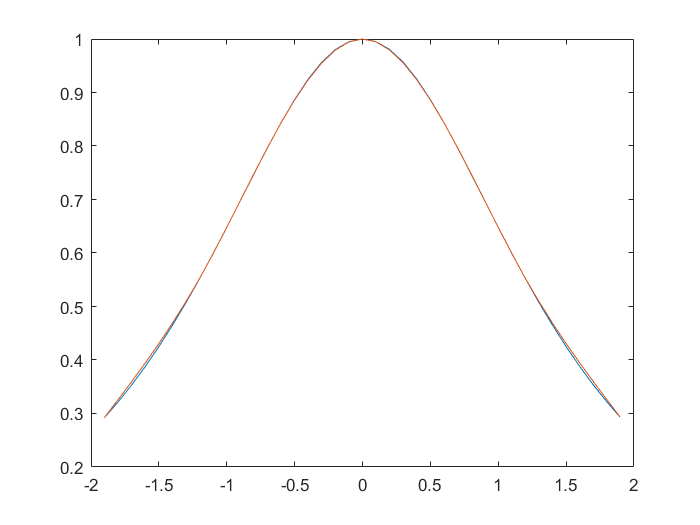


xval = x(1):0.1:x(n);
for i = 1:length(xval)
   yVal(i)=cubicEval(x,coeff,xval(i));
end
plot(xval,1./cosh(xval));
hold on
plot(xval,yVal);
hold off;

EuNorm = norm(yVal-1./cosh(xval));
%calculate the euclid norms
disp(EuNorm);

    0.0178



### **Question 4 [30%]**

**Part a: [15 %]**

Using the MATLAB command "meshgrid", create a $100\;\times \;100$ grid on the interval $x,y$$\in \left\lbrack -1,1\right\rbrack$. Create the discretized values of the function $f\left(x,y\right)=x^3 +3{\textrm{yx}}^2$ in this interval. Calculate 2D distributions of $\frac{\partial f}{\partial x}$ and  $\frac{\partial f}{\partial y}$ using finite difference schemes (use central difference for interior points and forward/backward difference for the points on the boundary). Plot the numerically calculated profiles of  $\frac{\partial f}{\partial x}$ and  $\frac{\partial f}{\partial y}$ on planes$x=0$ and $y=0\ldotp 5$and compare them with the analytical profiles of the derivatives.

**Answer:**

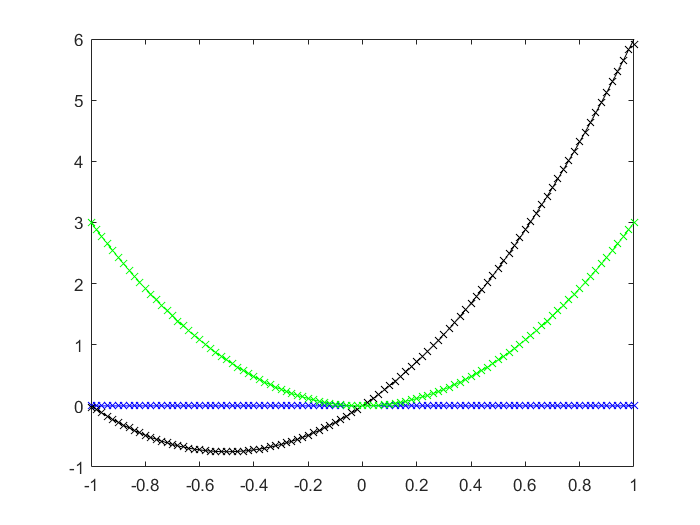

clear
clc

x(1,:)=[-1:0.02:1];
y(:,1)=[-1:0.02:1];
[xmesh,ymesh] = meshgrid(x,y);
%xmesh, x changes with colums, rows are the same;
%ymesh, y changes with rows, colums are the same;

diffx=zeros(101);
diffy=zeros(101);
for j=1:101
   for i=2:100
        diffx(j,i) = (fx4(xmesh(j,i+1),ymesh(j,i-1))-fx4(xmesh(j,i-1),ymesh(j,i-1)))/0.04;    
        diffy(i,j) = (fx4(xmesh(i,j),ymesh(i+1,j))-fx4(xmesh(i,j),ymesh(i-1,j)))/0.04;
   end
end
%diffx, x changes along columns
%diffx, y changes along rows;

%forward difference
diffx(:,1)=(fx4(xmesh(:,2),ymesh(:,2))-fx4(xmesh(:,1),ymesh(:,1)))./0.02;
diffy(1,:)=(fx4(xmesh(2,:),ymesh(2,:))-fx4(xmesh(1,:),ymesh(1,:)))./0.02;
%backward difference
diffx(:,101)=(fx4(xmesh(:,101),ymesh(:,101))-fx4(xmesh(:,100),ymesh(:,100)))./0.02;
diffx(101,:)=(fx4(xmesh(101,:),ymesh(101,:))-fx4(xmesh(100,:),ymesh(100,:)))./0.02;

diffxA = fx4Odx(xmesh,ymesh);
diffyA = fx4Ody(xmesh,ymesh);

%x=0 fixed,i=51;y=0.5 fixed,j=76
plot(y,diffx(:,51),'xr');
hold on
plot(y,diffxA(:,51),'-r');
hold on

plot(y,diffy(:,51),'xb');
hold on
plot(y,diffyA(:,51),'-b');
hold on

plot(x,diffx(76,:),'xk');
hold on
plot(x,diffxA(76,:),'-k');
hold on

plot(x,diffy(76,:),'xg');
hold on
plot(x,diffyA(76,:),'-g');

**Part b: [15 %]**

Use the systematic method to construct the finite-difference approximation of  $\frac{{\mathrm{d}}^4 f}{\mathrm{d}x^4 }$ using the stencil $\left(-2,-1,0,1,2\right)$. Report the coefficients obtained and the order of the truncation error in this approximation. Comment under which circumstance this approximation will provide an exact solution.

**Answer:**



%sampling = [-2,-1,0,1,2];
stencil = [-2,-1,0,1,2];
%finite-difference approximation


$$\frac{d^4 U}{dx^4 }{\left(x_i \right)}=a_{-2} U_{i-2} +a_{-1} U_{i-1} +a_0 U_i +a_1 U_{i+1} +a_2 U+\in_{trunc}$$


Get the taylor series expansion and stencil = [-2, -1, 0, 1, 2];


$$\frac{d^4 U}{dx^4 }{\left(x_i \right)}=a_2 {\left[U_i -2U_i^{\prime } \frac{∆x}{1!}+4U_i^{\prime \prime } \frac{\left(∆{\left.x\right)}^2 \right.}{2!}-8U_i^{\prime \prime \prime } \frac{\left(∆{\left.x\right)}^3 \right.}{3!}+16U_i^{\prime \prime \prime \prime } \frac{\left(∆{\left.x\right)}^4 \right.}{4!}+\dots \right]}+a_{-1} {\left[U_i -U_i^{\prime } \frac{∆x}{1!}+U_i^{\prime \prime } \frac{\left(∆{\left.x\right)}^2 \right.}{2!}-U_i^{\prime \prime \prime } \frac{\left(∆{\left.x\right)}^3 \right.}{3!}+U_i^{\prime \prime \prime \prime } \frac{\left(∆{\left.x\right)}^4 \right.}{4!}+\dots \right]}+a_0 U_i +a_1 {\left[U_i +U_i^{\prime } \frac{∆x}{1!}+U_i^{\prime \prime } \frac{\left(∆{\left.x\right)}^2 \right.}{2!}+U_i^{\prime \prime \prime } \frac{\left(∆{\left.x\right)}^3 \right.}{3!}+U_i^{\prime \prime \prime \prime } \frac{\left(∆{\left.x\right)}^4 \right.}{4!}+\dots \right]}\ +a_2 {\left[U_i +2U_i^{\prime } \frac{∆x}{1!}+4U_i^{\prime \prime } \frac{\left(∆{\left.x\right)}^2 \right.}{2!}+8U_i^{\prime \prime \prime } \frac{\left(∆{\left.x\right)}^3 \right.}{3!}+16U_i^{\prime \prime \prime \prime } \frac{\left(∆{\left.x\right)}^4 \right.}{4!}+\dots \right]}$$


Then solve to get the coefficients.


$${\left[\begin{array}{ccccc}
1 & 1 & 1 & 1 & 1\\
-2 & -1 & 0 & 1 & 2\\
4 & 1 & 0 & 1 & 4\\
-8 & -1 & 0 & 1 & 8\\
16 & 1 & 0 & 1 & 16
\end{array}\right]}{\left[\begin{array}{c}
a_{-2} \\
a_{-1} \\
a_0 \\
a_1 \\
a_2 
\end{array}\right]}={\left[\begin{array}{c}
0\\
0\\
0\\
0\\
\frac{4!}{\left(∆{\left.x\right)}^4 \right.}
\end{array}\right]}$$


Thus,


$$\frac{d^4 U}{dx^4 }{\left(x_i \right)}=\frac{U_{i-2} -4U_{i-1} +6U_i -4U_{i+1} +U}{\left(∆{\left.x\right)}^4 \right.}+\in_{trunc}$$


The trunction error then should be: $\in_{trunc} =\frac{d^5 U}{dx^5 }{\left(x_i \right)}$

As a result, the order of the trunction error is 5. $\in_{trunc}$ should be zero to get the exact solution, the fifth spatial derivative of $U$is 0.

function f = fx4(x,y)
    f=x.^3+3.*y.*x.^2;
end

function diff = fx4Odx(x,y)
    diff=3.*x.^2+6.*x.*y;
end

function diff = fx4Ody(x,y)
    diff = 3.*x.^2;
end


function y = fx(x)
 y = cos(x).*(exp(2.*x) - 2.*exp(x) + 1);
end


function dydx = fbarX(x)
 dydx = -sin(x) .*(exp(2.*x) - 2.*exp(x) + 1) + cos(x) .*(2.*exp(2.*x) - 2.*exp(x));  
end


function x=x2t(t)
    x=(3.*t+1)./2;    
end


function y = fx2B(x)
 y=3.*x.^9+2.*x.^4+1.*x;
end


function xj = chebyshev(N,i)
xj = -cos(((2.*i+1)/(2.*N+2)).*pi);
end


function polyArray=CubicSpline(x,fx)
n=length(x);%find the length of the array
m=zeros(n,1);%create the array with zeros used after as both the initial and the last values are zero
mat_h=zeros(n-2);%create the matrix for the collection of h as majority part is zero

for i=1:(n-1)
    h(i)=x(i+1)-x(i);%get the interval
end

%try to create matrix which can solve m, need to rearrange the matrix to
%make it a square matrix which has inverse
%in this occation, y is a 7X1 matrix with fi and hi with i from 2 to n-1
y(1:n-2,1)=6.*(((fx(3:n)-fx(2:n-1))./h(2:n-1)-(fx(2:n-1)-fx(1:n-2))./h(1:n-2)));%create the matrix for the f and h, which are in the equation of h and m

%the matrix for h is special create the 1 ad n-2 which contain 2 values
%each. The matrix is 7X7 with hi from 2 to n-1
mat_h(1,[1,2])=[2*(h(2)+h(1)),h(2)];
mat_h(n-2,[n-3,n-2])=[h(n-2),2*(h(n-2)+h(n-1))];%the first and the last row are special as it eliminates h1 and h8 as the m1 and mN are both zero so there are 2 values in that row
%create rows which contain 3 values each
for n2=3:n-2
    mat_h(n2-1,[(n2-2),n2-1,n2])=[h(n2-1),2*(h(n2-1)+h(n2)),h(n2)];%fill the value in the matrix with hi-1, 2*(hi-1+hi) and hi
end

%solve the m by array operations from 2 to n-1 as 1 and n are both 0
m(2:n-1,1)=mat_h\y;
%can use loops instead, but is will be more organized while array
%operations will be faster
a(1:n-1,1)=fx(1:n-1)';
b(1:n-1,1)=((fx(2:n)'-fx(1:n-1)')./h(1:n-1)')-(h(1:n-1)'.*(2.*m(1:n-1,1)+m(2:n,1))./6);%the dimensions need to be the same
c(1:n-1,1)=m(1:n-1,1)./2;
d(1:n-1,1)=(m(2:n,1)-m(1:n-1,1))./(6.*h(1:n-1)');
%fill the arguments using array operations, the dimension of each
%coefficients is (n-1)x1

polyArray=[d,c,b,a];%the output is a N-1x4 array as there are n-1 intervals

end


function yInterpVal = cubicEval(x,polyArray,xval)

%cubicEval - Function to evaluate value of polynomial function described by
%array polyArray[] at x-position xval.
%Correct polynomials for xval are selected by using bisection search to
%determine the correct interval in x where xval is located.
%
%OUTPUTS
%yInterpVal - The value of the function evaluated at xval
%INPUTS
%x - Vector containing x-values for sample dataset, in ascending order.
%polyArray - N x 4 Array containing polynomial coefficients for cubic spline at
%            each interval, where N is number of intervals.  Make
%            sure coefficients in each row are ordered in descending order, i.e
%            coefficients of x^3, x^2, x^1, x.  Rows to be ordered by
%            ascending x-position of interval.
%xval - Scalar x-value at which you would like to evaluate the function.

%calculate number of x-values
n=length(x);

%%use bisection search to determine which segment the interpolation "xval"
%%lies in
%initialise search to full range of x
klower = 1;
kupper = n;
%IF statement to check that xval lies within the sample data range
if (xval >= x(1) && xval <= x(n))
while (kupper - klower > 1) %continue search until search interval has reduced to two consecutive points
    kmid = ceil((klower + kupper)/2); %split domain in half and move to the half containing xval
    if (xval < x(kmid))
        kupper=kmid;
    else
        klower=kmid;
    end
end
else
    %If xval not within the x-range of the dataset print error and return
    %NaN
    disp('Error: Please enter an interpolation x-value "xval" that lies within the range of x');
    yInterpVal=NaN;
    return;
end

%use correct set of polynomials from the appropriate row in polyArray to
%evaluate polynomial using polyval() function.
yInterpVal = polyval(polyArray(klower,:),(xval-x(klower)));

end
